# Exercise 4.2 - Effort-Based Control using the Dynamic Model 

In this exercise, you will implement a **joint-space PD controller** with **gravity and dynamic compensation** for a UR manipulator. The goal is to drive all joints of the robot smoothly toward a desired configuration (`qd`) while respecting joint torque limits.

## Task

Your controller will operate in the **effort control mode**, meaning it will directly send **joint torques** to the simulated robot.

At each control step, you will:

- Read the current joint positions and velocities from the simulator.

- Compute the dynamic model of the robot (mass matrix, Coriolis/centrifugal terms, and gravity torques).

- Calculate the control torques using a PD law in the joint space.

- Apply **torque saturation** to stay within physical actuator limits.

- Send the computed torques back to the simulator.

## Import the Robot

Instead of using the standard library of MATLAB, for this exercise import the robot using the raw URDF file. 

- importrobot(["robotics/Ros/src/ur5e.urdf"]);

Hint: Remember to set the gravity and data structure. While you can define the data structure during import, the gravity needs to be defined later. 

## Functions to Interface the Simulation

Use the following helper functions to communicate with the simulator:

- `[q, q_dot, ~] = GetJointValues('All') `Reads the current **joint positions** (`q`, in radians) and **joint velocities** (`q_dot`, in radians/second`) from the ROS network.Both are returned as 6×1 column vectors.

- `SendJointTorques(tau_sat)`Sends a 6×1 vector of torques (in **Nm**) to the robot joints.The command must respect the robot’s torque limits.

## **Controller Structure**

The implemented PD controller with dynamics compensation has the following general form:


$$\tau =M\left(q\right)\cdot v+C\left(q,\dot{q} \right)\cdot \;\dot{q} +g\left(q\right)$$


with the input v: 


$$v=\left(\textrm{Kp}\cdot e+\textrm{Kd}\cdot \dot{e} \right)$$


and the errors: 


$$e=q_{\textrm{desired}} -q$$


$\dot{e} =\dot{q_{\textrm{desired}} } -\dot{q}$ in our case $\dot{q_{\textrm{desired}} } =0$

and a gravity of $\left\lbrack \begin{array}{c}
0\\
0\\
-9\ldotp 81
\end{array}\right\rbrack$

## Gain Design

This scheme doesn't require high gains, as the non linearities are canceled by the dynamic terms and the input is scaled by the inertia matrix. Start by defining the diagonal gain matrices using this approach: 


$${\textrm{Kp}}_i \;=\;\omega_i^2$$



$${\textrm{Kd}}_i \;=\;2\cdot \;\zeta \cdot \omega_{i\;}$$


with 


$$\zeta =0\ldotp 7$$


and


$$\omega_i =\frac{4}{\;\zeta \cdot T_{s,i} }$$
 

using $T_{s,i} \in \left\lbrack 0\ldotp 8,1\ldotp 5\right\rbrack$. Give a larger settling time to the joints with higher torque limits. 

### Gain Tuning 

Analyze the behavior of Kp and Kd and their impact on the robot behaviour. Gradually scale Kp and/or Kd to stabilize the robot in its home position $q=\left\lbrack 0,-\frac{\pi }{2},0,-\frac{\pi }{2},0,0\right\rbrack$

## Torque Saturation

Real robots cannot produce infinite torque.

To avoid unrealistic commands, you must apply **torque saturation**. 


$$\tau_{\textrm{sat}} \le \tau_{\max }$$


Use the figure below to construct the torque limit vector specific to your robot. 

(If you simulate a different robot, make sure to update the torque limits)

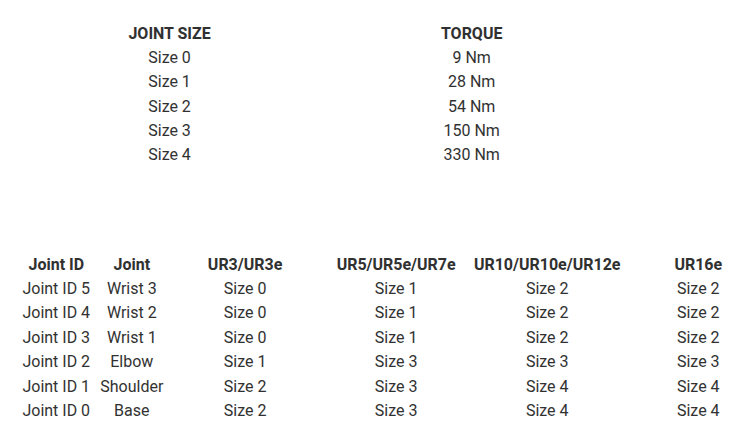

## Timing

You can control the frequency of your controller using the functions: 

- r = rateControl(frequency)

- waitfor(r)

## Other properties: 

This controller needs to be fast. Try to achieve a frequency of 50 - 200 Hz for a stable simulation. If your hardware is not capable of this, you can reduce the simulation speed using the function:

- SetSimulationSpeed(Speedfactor) with Speedfactor $\in \left(\left\lbrack 0,1\right\rbrack \right)$

- or SetSimulationSpeed(Speedfactor, 'docker',false) for native Ubuntu 

## Optional Visualization: 

You can store the joint states, speeds and torques and visualize them using the function: 

- plotTrajectory(qstorage, qdstorage, tau_storage)

Start the Simulation by running: 

% StartTutorialApplication('Simulation','Controller', 'Effort', 'Model','ur3e');
%If you use ROS on a native Ubuntu system use:
StartTutorialApplication('Simulation','Controller', 'Effort', 'Model','ur3e', 'Docker', false);

gz-modified


To see the path of the end effector you can run: 

% StartTutorialApplication('Trajectory');
%If you use ROS on a native Ubuntu system use:
% StartTutorialApplication('Trajectory', 'Docker', false);
% StartTutorialApplication('Safety_nodes','docker',false); %sends a 0 torque when no other command has been sent

gz-modified


#### Load the Robot and setup the gravity vector       

robot = importrobot(["robotics/Ros/src/ur3e.urdf"], DataFormat="column");
g  = [0 0 -9.81];
robot.Gravity = g;


#### Setup your Parameters here

qd1      = zeros(6,1);                   
qd2     = [0,-pi/2,0,-pi/2,0,0]';
qd3 =     [pi/2,pi/4,pi/5,-pi/2,0,pi]';

dt = 0.005;                               
r  = rateControl(1/dt);

tau_lim = [54,54,28,9,9,9]';

Chi = 0.7;
w_i = 4./(Chi*linspace(1.5,0.8,6));
Kp = 2*diag(w_i.^2);
Kd = 3*diag(2*Chi*w_i);

#### Setup your control loop

you can use tic and toc execute the while loop for a desired time. 

Check your hardware performance and see analyze your rate of publishing. To do this, increment a counter each loop execution and after the loop has finished divide by the elapsed time. 

count=0;

qstorage = [];
qdstorage = [];
tau_storage = [];
time = [];
t0=tic;

try
    while toc(t0)<15
        % 1) Read current state
        % [q, q_dot, ~,timenow] = GetJointValues('All');   % each 6x1
        [q, q_dot] = GetJointValues('All');
        timenow = toc(t0);

        q = q(:); q_dot = q_dot(:);
        if toc(t0)<5
            qd=qd1;
        elseif toc(t0)<10
            qd=qd2;
        else

            qd=qd3;
        end

        count=count+1;
        % 2) Dynamics
        M = massMatrix(robot, q);
        h = velocityProduct(robot, q, q_dot);    % C(q,dq)*dq
        G = gravityTorque(robot, q);

        % 3) Errors
        e  = qd - q;
        ed = -q_dot;

        % 4) Control input
        v = Kp*e + Kd*ed ;


        % 5) Full torque
        tau = (M*v + h + G);

        % 6) Saturation handling
        tau_sat = min(max(tau, -tau_lim), tau_lim);

        % 7) Send torques
        SendJointTorques(tau_sat);

        %Store states
        qstorage = [qstorage, q];
        qdstorage = [qdstorage, q_dot];
        tau_storage=[tau_storage, tau_sat];
        time = [time,timenow];
        count=count+1;
        waitfor(r);
    end
    time = time-time(1);
    true_rate = count/time(end)
catch ME
    warning('[reachZeroUREffort] Error: %s', ME.message);
end

true_rate = 42.3669

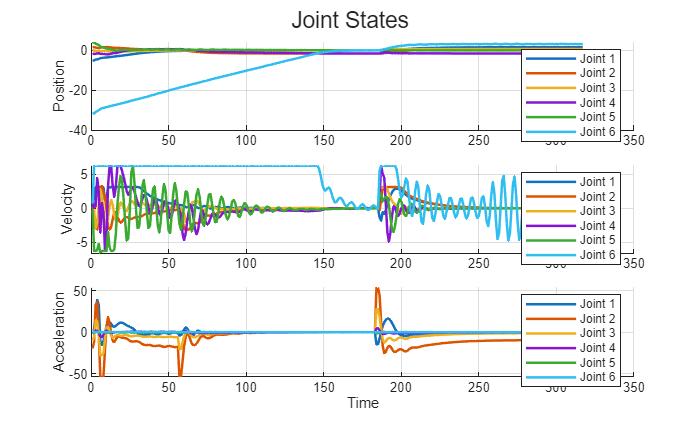

plotTrajectory(qstorage,qdstorage,tau_storage)

## Try a different Model 

Inspect the effects of an incorrect dynamics model by loading the ur3e robot into your MATLAB  workspace while simulating an ur5e model.

StopTutorialApplications('docker',false);

libmwros2server killed (pid 139511)
bash killed (pid 173099)
bash killed (pid 173100)
bash killed (pid 173102)
ros2 killed (pid 173175)
ros2 killed (pid 173176)
ros2 killed (pid 173177)
libmwros2server killed (pid 173815)
bash killed (pid 174236)
bash -lc "pkill -f -e 'ros2' 2>/dev/null || true": Terminated
bash killed (pid 174244)
bash -lc "pkill -f -e 'roscore' 2>/dev/null || true": Terminated
bash killed (pid 174257)
bash -lc "pkill -f -e 'rviz' 2>/dev/null || true": Terminated
bash killed (pid 174267)
bash -lc "pkill -f -e 'gazebo' 2>/dev/null || true": Terminated
ruby killed (pid 173236)
bash killed (pid 174275)
bash -lc "pkill -f -e 'gz' 2>/dev/null || true": Terminated
bash killed (pid 174283)
bash -lc "pkill -f -e 'ign' 2>/dev/null || true": Terminated
bash killed (pid 174291)
bash -lc "pkill -f -e 'ignition' 2>/dev/null || true": Terminated
bash killed (pid 174299)
bash -lc "pkill -f -e 'ros2 launch' 2>/dev/null || true": Terminated
bash killed (pid 174307)
bash -lc "pkill -f 

clear SendJointTorques GetJointValues

StartTutorialApplication('Simulation','Controller', 'Effort', 'Model','ur5e', 'Docker', false);
StartTutorialApplication('Trajectory', 'Docker', false);
StartTutorialApplication('Safety_nodes','docker',false); %sends a 0 torque when no other command has been sent

tau_lim = [150 150 150 28 28 28]'; %UR5e
robot = importrobot(["robotics/Ros/src/ur3e.urdf"], DataFormat="column");
g = [0,0,-9.81]';
robot.Gravity=g;